exit=0;
y_max=600;
x_max=300;
delta=0

delta = 0


x=x_max/2;
y=y_max/10;

hold on
sprite=plot(x,y,'O');
bullet=[]


bullet =

     []



bull0bj=plot(0,0,'o')

bull0bj =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0
              YData: 0
              ZData: [1×0 double]

  Show all properties


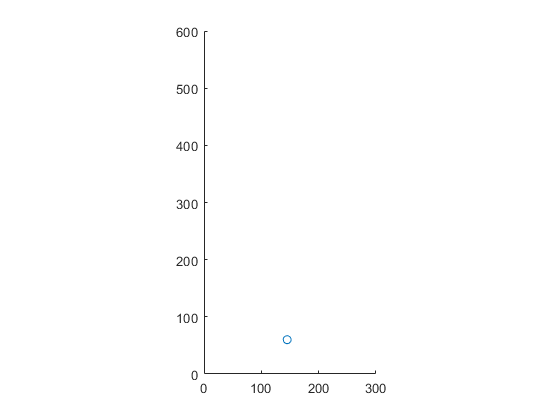


axis manual
axis([0 300 0 600]);
daspect([1,1,1])

time_step=0.05;
space_step=5;

addpath('get_state')
while ~exit
    [delta,fire,exit]=get_state();
    x=x+delta*space_step;
    if (x>x_max || x<0)
        exit=1;
        break
    end
    set(sprite,'XData',[x],'Ydata',[y]);
    bullet=generate_bullet(bullet,fire,x,y,y_max,space_step);
    if ~isempty(bullet)
        set(bull0bj,'XData',[bullet(:,1)],'Ydata',[bullet(:,2)]);
    else
        set(bull0bj,'XData',[-10],'Ydata',[-10]);
    end
%     [collision,enemies,num_enemies,hit,level,bullet]=check_enemies(bullet,enemies,num_enemies,level)
%     if collision==1
%         exit=1;
%     end
    pause(time_step)
end